# Reading Weights from files

clc; clear;

N = 400;
baseDir = fullfile('Data', 'Scaled50', ['N' num2str(N)]);
folders = dir(baseDir);

% Filter only simulation subfolders
folders = folders([folders.isdir] & ~ismember({folders.name}, {'.', '..'}));
nFolders = length(folders);
nMemories = 100;
nSynapses = round(N*0.8) * 20;

% Preallocate 3D matrix: [memory × simulation × synapses]
w_all = nan(nMemories, nFolders, nSynapses);  % Use NaN for missing data

for f = 1:nFolders
    simFolder = folders(f).name;
    fprintf('Processing: %s\n', simFolder);

    for mem = 1:nMemories
        try
            filePath = fullfile(baseDir, simFolder, ...
                ['ttfs_mem' num2str(mem) '.mat']);
            S = load(filePath, 'net');

            net = S.net;
            mask = net.Adjacency_matrix(1:net.Ne, 1:net.Ne);
            w = net.w(1:net.Ne, 1:net.Ne);
            w = w(mask);  % flatten to 1D vector of connected weights

            w_all(mem, f, :) = w;
        catch
            warning('Skipped: %s (missing or corrupt)', filePath);
        end
    end
end

Processing: Apr_16_2025_16_42_42
Processing: Apr_16_2025_23_54_35
Processing: Apr_17_2025_07_34_17
Processing: Apr_17_2025_14_37_04
Processing: Apr_21_2025_11_43_49
Processing: Apr_21_2025_19_11_44
Processing: Apr_22_2025_03_05_51
Processing: Apr_22_2025_16_59_12
Processing: Apr_23_2025_00_13_35
Processing: Apr_23_2025_06_50_15


# Weights Correlation Matrix (Sequential Learning) for a single simulation

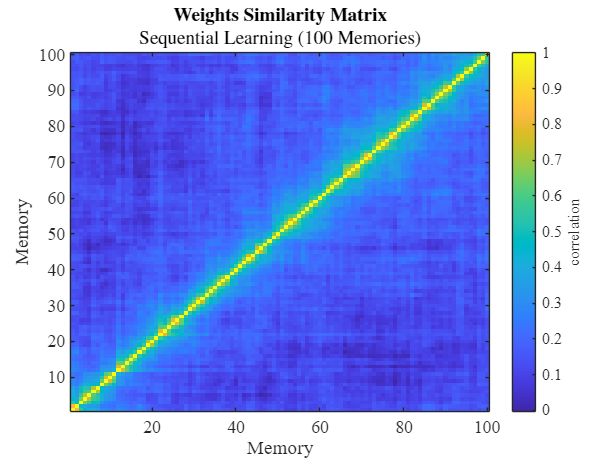


mat = 1 - squareform(pdist(squeeze(w_all(:, 1, :)), 'correlation'));

figure;
imagesc(mat);
cb = colorbar();
cb.Label.String = 'correlation';
xlabel('Memory');
ylabel('Memory');
title({'\textbf{Weights Similarity Matrix}', 'Sequential Learning (100 Memories)'}, 'Interpreter','latex');
set(gca, 'FontSize', 12, 'FontName', 'Times New Roman', 'Ydir', 'normal');
print("WeigthCorrelationMat.png", '-dpng', '-r300')

# Single Simulation Weight Similarity

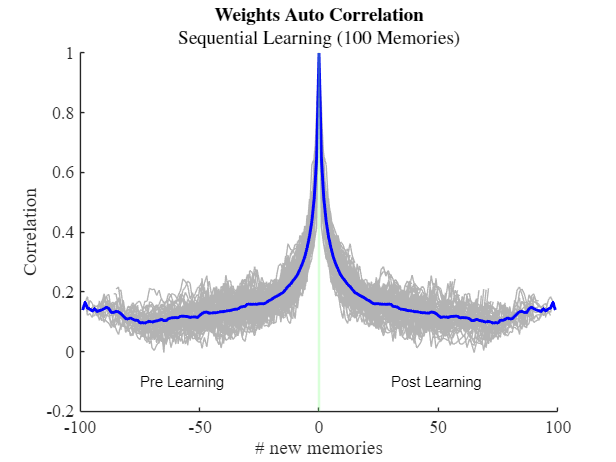


signal = nan(100, 199);

for m = 1:100
    signal(m, (100:199)-m+1) = mat(m, :);
end

% Compute mean and percentile-based confidence interval
mu = nanmean(signal, 1);                     % Mean across rows
low = prctile(signal, 2.5, 1);               % 2.5th percentile
high = prctile(signal, 97.5, 1);             % 97.5th percentile

x = (1:199) - 100;

% Mask NaNs
valid = ~isnan(mu) & ~isnan(low) & ~isnan(high);
x = x(valid);
mu = mu(valid);
upper = high(valid);
lower = low(valid);

figure; hold on;
plot(repmat(x, 100, 1)', signal(:, valid)', 'Color', [0.7 0.7 0.7], 'LineWidth', 0.1);   % All trials

% fill([x, fliplr(x)], [upper, fliplr(lower)], ...
%      [0.3 0.6 1], 'FaceAlpha', 0.4, 'EdgeColor', 'none');  % Spread band (95% range)

plot(x, mu, 'b', 'LineWidth', 2);  % Mean trace

text(30, -0.1, "Post Learning")
text(-75, -0.1, "Pre Learning")

fill([-0.5 0.5 0.5 -0.5], ...
     [-0.2 -0.2 1 1], ...
     [0.5 1 0.5], 'FaceAlpha', 0.3, 'EdgeColor', 'none');

xlabel('# new memories');
ylabel('Correlation');
title({'\textbf{Weights Auto Correlation}', 'Sequential Learning (100 Memories)'}, 'Interpreter','latex');
set(gca, 'FontSize', 12, 'FontName', 'Times New Roman');

# Grand Average on independant simulations

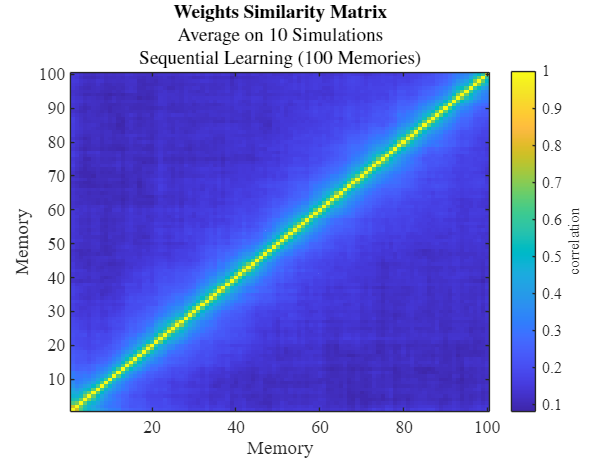


sim_mats = zeros(nMemories, nMemories, nFolders);  % [mem × mem × sim]

for f = 1:nFolders
    W = squeeze(w_all(:, f, :));  % [100 × 6400] for simulation f

    % Compute cosine similarity matrix
    D = pdist(W, 'correlation');            % 1 - cosine sim
    S = 1 - squareform(D);             % similarity matrix
    sim_mats(:, :, f) = S;
end

% Average across simulations
avg_mat = mean(sim_mats, 3, 'omitnan');

% Plot
figure;
imagesc(avg_mat);
cb = colorbar();
cb.Label.String = 'correlation';
xlabel('Memory');
ylabel('Memory');
title({'\textbf{Weights Similarity Matrix}', ...
        'Average on 10 Simulations', ...
       'Sequential Learning (100 Memories)'}, ...
       'Interpreter', 'latex');
set(gca, 'FontSize', 12, 'FontName', 'Times New Roman', 'YDir', 'normal');

# Grand Average on independant simulations

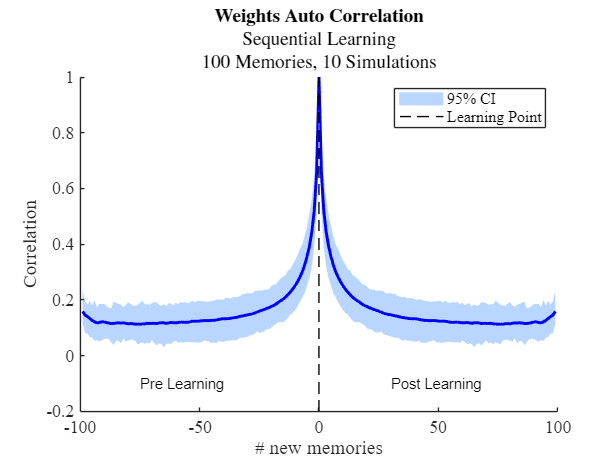

signal_all = nan(nFolders, nMemories, 199);

for j = 1:nFolders
    for m = 1:100
        signal_all(j, m, (100:199)-m+1) = sim_mats(m, :, j);
    end
end

% Assuming: signal_all [100 × 199 × nSimulations]
nSims = nFolders;
x = (1:199) - 100;

% Reshape into [trials × time] format
signal_reshaped = reshape(signal_all, [], 199);  % [nFolders * nMemories × 199]

mu = nanmean(signal_reshaped, 1);                % Mean across all trials
low = prctile(signal_reshaped, 2.5, 1);          % 2.5th percentile
high = prctile(signal_reshaped, 97.5, 1);        % 97.5th percentile

% Remove NaNs
valid = ~isnan(mu) & ~isnan(low) & ~isnan(high);
x = x(valid);
mu = mu(valid);
upper = high(valid);
lower = low(valid);


% Plot
figure; hold on;

% Plot individual curves for each sim if desired
% for s = 1:nSims
%     plot(x, squeeze(nanmean(signal_all(s, :, valid), 1)), ...
%          'Color', [0.8 0.8 0.8], 'LineWidth', 0.5);
% end

% CI band
fill([x, fliplr(x)], [upper, fliplr(lower)], ...
     [0.3 0.6 1], 'FaceAlpha', 0.4, 'EdgeColor', 'none', DisplayName='95% CI');

% Mean line
plot(x, mu, 'b', 'LineWidth', 2, HandleVisibility='off');

text(30, -0.1, "Post Learning")
text(-75, -0.1, "Pre Learning")

% fill([-0.5 0.5 0.5 -0.5], ...
%      [-0.2 -0.2 1 1], ...
%      [0.5 1 0.5], 'FaceAlpha', 0.3, 'EdgeColor', 'none', DisplayName='Learning Point');

plot([0, 0], [-0.2, 1], LineStyle='--', Color='k', DisplayName='Learning Point')
legend()

ylim([-0.2, 1])
xlabel('# new memories');
ylabel('Correlation');
title({'\textbf{Weights Auto Correlation}', 'Sequential Learning', sprintf('100 Memories,  %d Simulations', nFolders)}, 'Interpreter','latex');
set(gca, 'FontSize', 12, 'FontName', 'Times New Roman');
print("WeightsAutoCorrelation.png", '-dpng', '-r300')

rand(nSynapses, 1)

Unrecognized function or variable 'nSynapses'.